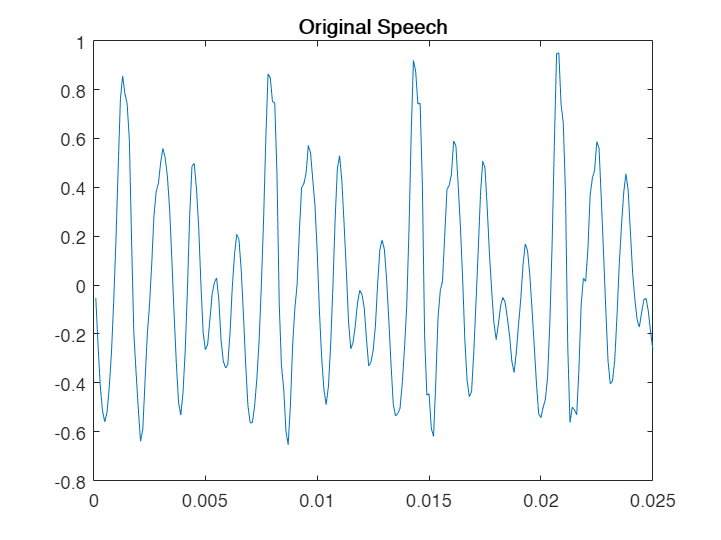

[speech, Fs] = audioread('./speech1_10k.wav');
range = (1:length(speech))/Fs;
plot(range, speech);
title('Original Speech');

window_duration = 0.025;
shift_duration = 0.015;
window = hamming(window_duration*Fs);
shift = shift_duration*Fs;

w_speech = zeros(1, length(window) * ...
    ceil(length(speech)/length(window)));
w_speech(1:length(speech)) = speech;
% speech = w_speech;
num_shifts = ceil((length(speech) - length(window))/shift);
num_windows = num_shifts+1;

windowed_speech = zeros(num_windows, length(window));
for i=0:num_windows-1
    windowed_speech(i+1, :) = ...
    speech(i*shift+1:(i*shift)+length(window)) .* window';
end

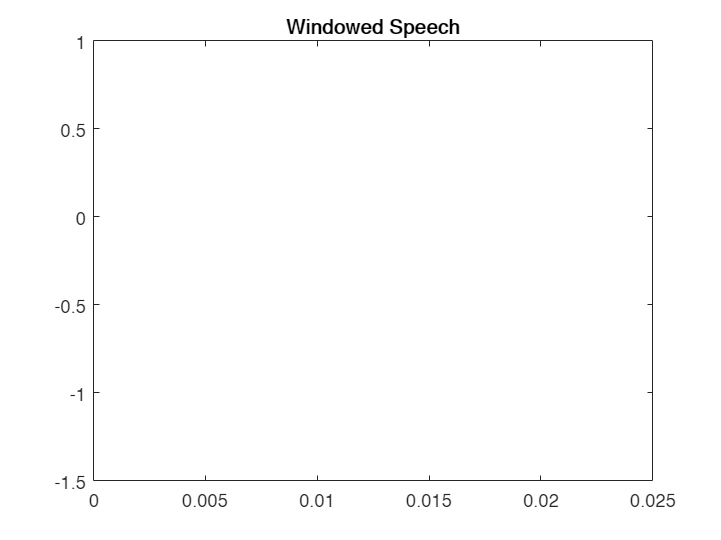

range_win = (1:length(window))/Fs;
for i=1:num_windows
    figure;
    plot(range_win+(i-1)*window_duration, speech(i, :));
end
title('Windowed Speech')

% xlim([0.0000 0.0250])
% ylim([-0.61 0.94])

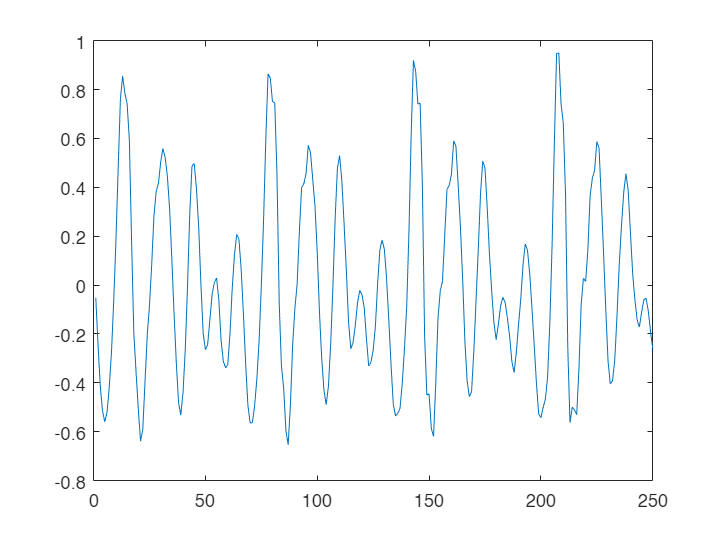

plot(speech)

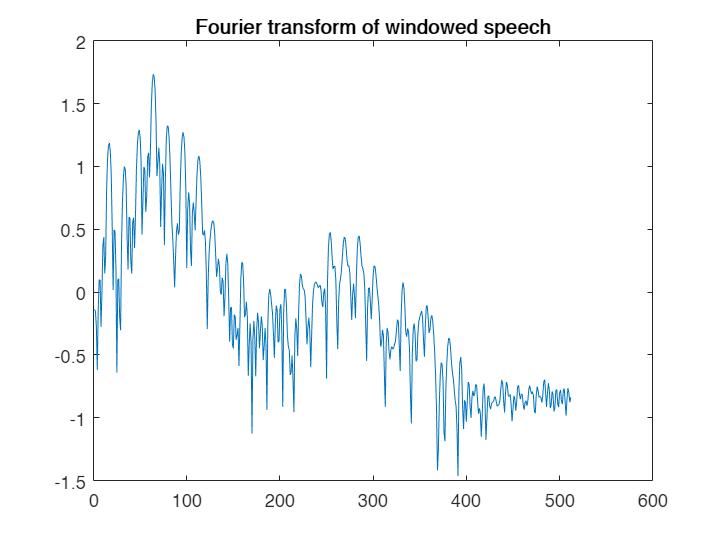

freq = fft(speech,1024);
plot(log10(abs(freq(1:512))));
title('Fourier transform of windowed speech')

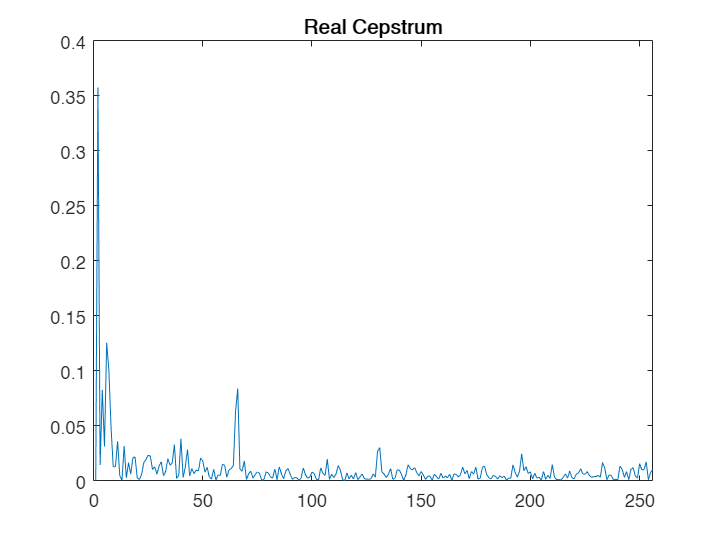

rcep = ifft(log10(abs(freq)));
rcep(1) = 0;
plot((1:256), abs(rcep(1:256)));
title('Real Cepstrum')
xlim([0,256])

lifter = zeros(1, length(rcep));
lifter(1) = 1;
lifter(2:49) = 2;

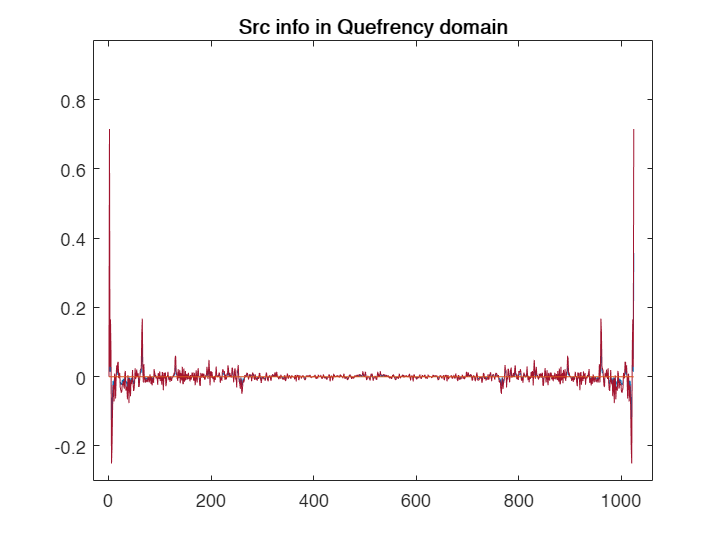

srcInfo = rcep.*lifter;
plot(srcInfo);
title('Src info in Quefrency domain')

xlim([-29 1061])
ylim([-0.30 0.97])

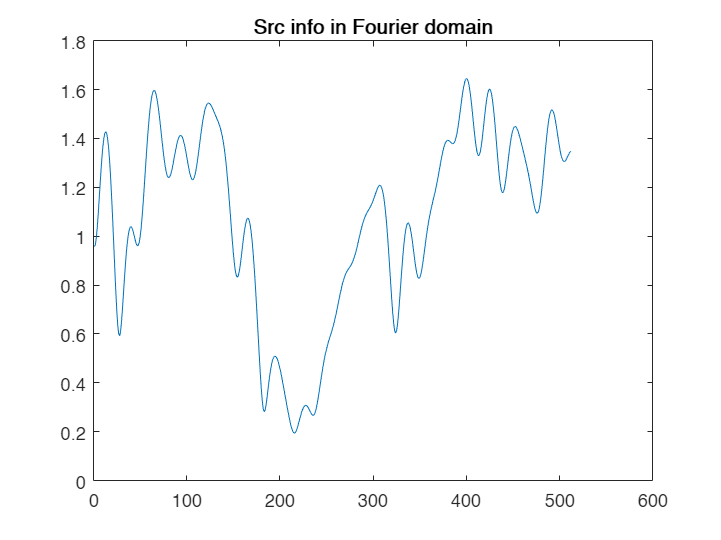

srcFft = fft(srcInfo);
plot(abs(srcFft(1:512)));
title('Src info in Fourier domain')

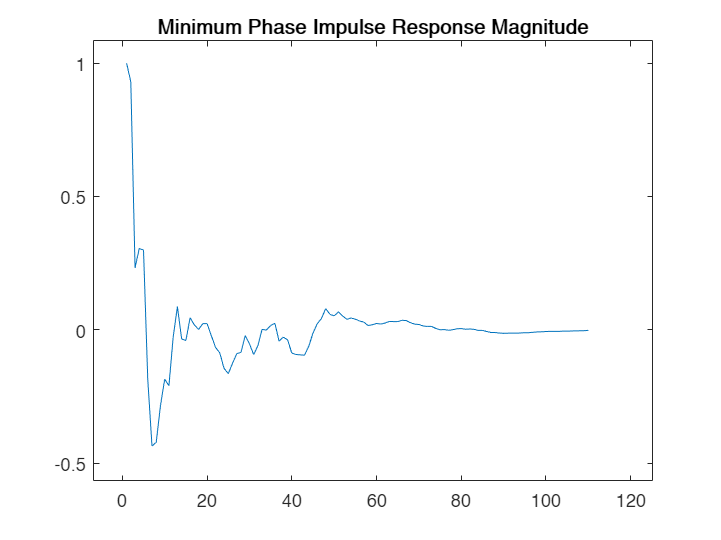

% minResponse = ifft(exp(srcFft));
minResponse = ifft(exp(fft(srcInfo))); 
% minResponse(1)=0;
plot(minResponse(1:110));
title('Minimum Phase Impulse Response Magnitude')

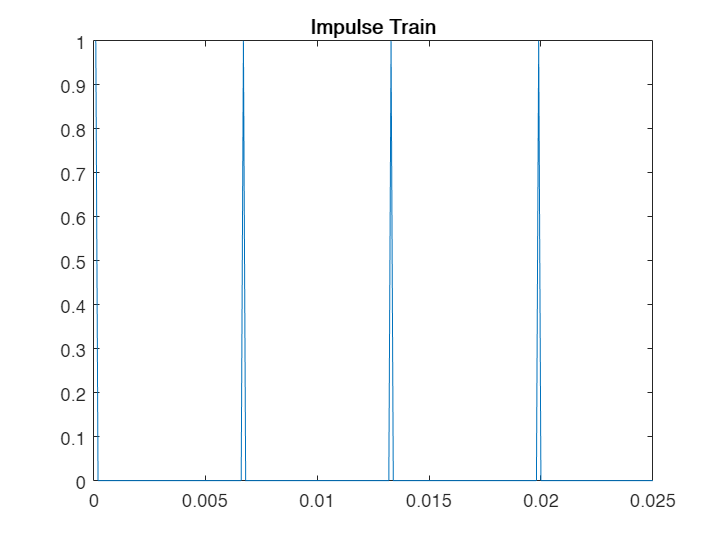

% Pitch period is 66
impTrain = zeros(1, length(speech));
for i=1:66:length(speech)
    impTrain(i)=1;
end
plot(range_win, impTrain)
title('Impulse Train');

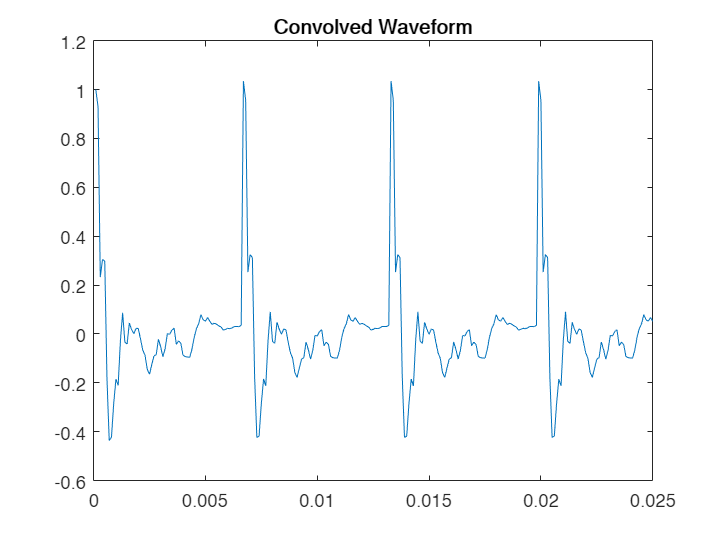

convolved_speech = conv(minResponse(1:110), impTrain, "full");
plot(range_win, convolved_speech(1:length(speech)));
title('Convolved Waveform');